%% Esercitazione: Assegnamento degli autovalori — da SISO a MIMO (Sylvester & place)
% File: Esercitazione_Assegnamento_Autovalori.m
% Esempi pratici per aula su SISO (3D), aggiunta integratore e MIMO
% con confronto tra place() e approccio Sylvester.

%% Parametri e sistema di riferimento (Parte A: SISO 3D)
% Sistema SISO di terzo ordine con poli -1,-2,-3 (polinomio (s+1)(s+2)(s+3))
A = [0 1 0; 0 0 1; -6 -11 -6];
B = [0;0;1];
C = [1 0 0];   % uscita scelta per l'esempio
disp('--- Parte A: sistema SISO 3D ---')

--- Parte A: sistema SISO 3D ---


disp('Autovalori nominali di A:'); disp(eig(A).')

Autovalori nominali di A:
   -1.0000   -2.0000   -3.0000




% Verifica controllabilità
ctrbRank = rank(ctrb(A,B));
fprintf('Rango matrice di controllabilità: %d\n', ctrbRank);

Rango matrice di controllabilità: 3



%% Esercizio A: posizionamento dei poli (SISO)
% Obiettivo: spostare i poli in p = [-4 -5 -6]
p_A = [-4 -5 -6];
K_A = -acker(A,B,p_A);   
Acl_A = A + B*K_A;
fprintf('K (SISO) = '); disp(K_A);

K (SISO) =   -114   -63    -9



fprintf('Poli anello chiuso (SISO): '); disp(eig(Acl_A).');

Poli anello chiuso (SISO):    -4.0000   -5.0000   -6.0000



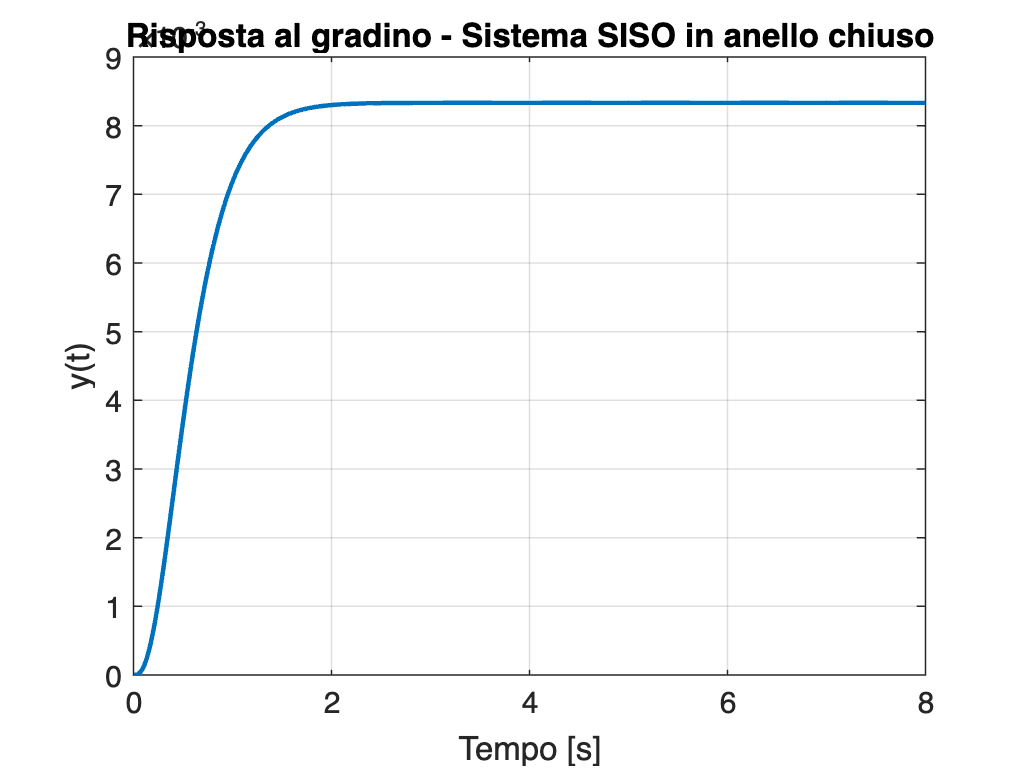




% Simulazione tempo dominio (step)
t = 0:0.01:8;
sys_cl_A = ss(Acl_A, B, C, 0);
y_step_A = step(sys_cl_A, t);

figure('Name','Parte A: risposta al gradino');
plot(t, y_step_A, 'LineWidth', 1.5);
grid on; title('Risposta al gradino - Sistema SISO in anello chiuso');
xlabel('Tempo [s]'); ylabel('y(t)'); hold on;

%plot(t, ones(size(t))*1, '--k'); legend('y(t)','r(t)=1');

%% Parte B: Aggiunta dell'azione integrale (integrazione dell'errore)
% Aggiungiamo stato integrale xI = ∫(r - y) dt
A_aug = [A zeros(3,1); -C 0];
B_aug = [B; 0];
C_aug = [C 0];

disp('--- Parte B: integrazione dell errore (stato aumentato) ---')

--- Parte B: integrazione dell errore (stato aumentato) ---


disp('Dimensione sistema aumentato:'); disp(size(A_aug));

Dimensione sistema aumentato:
     4     4




% Scegli poli per il sistema aumentato (esempio)
p_B = [-3 -4 -5 -6];   % quattro poli (ultimo per integratore)
K_aug = -acker(A_aug, B_aug, p_B);   % K_aug = [Kx, Ki]
Kx = K_aug(:,1:3);
Ki = K_aug(:,4);
fprintf('Kx = '); disp(Kx);

Kx =   -336  -108   -12



fprintf('Ki = '); disp(Ki);

Ki =    360



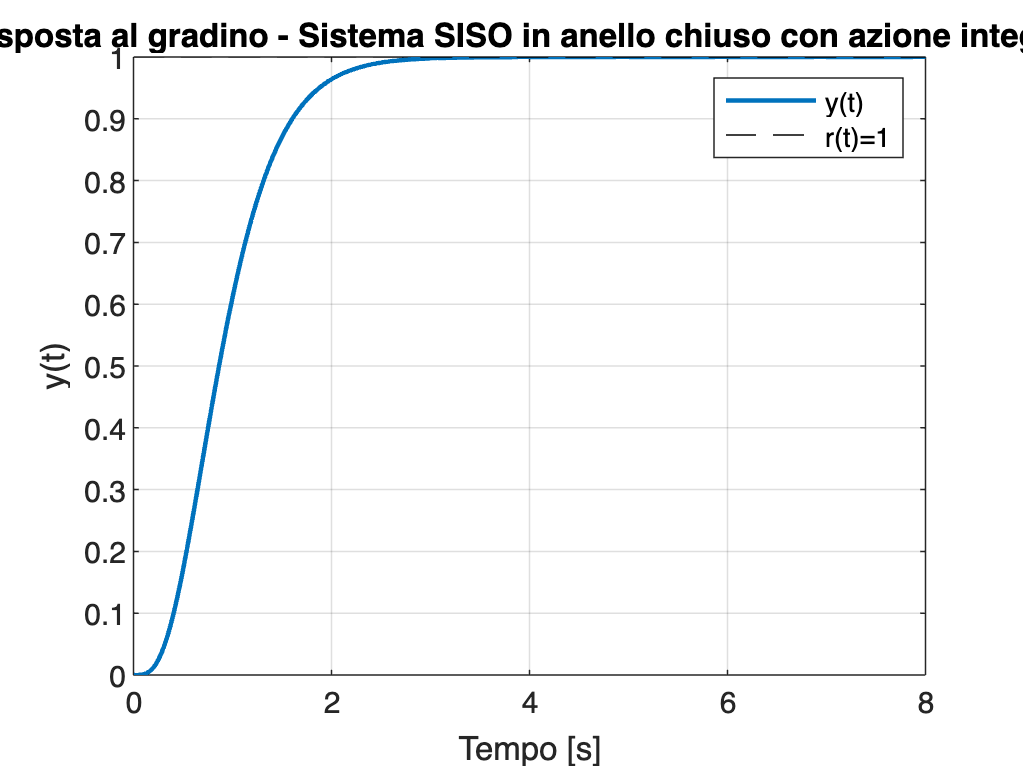


% Simulazione risposta a gradino con integratore 
Acl_aug = A_aug + B_aug*K_aug;
Bcl_aug=[0 0 0 1]';
sys_cl_B = ss(Acl_aug, Bcl_aug, C_aug, 0);
y_step_B = step(sys_cl_B, t);
figure('Name','Parte B: risposta al gradino');
plot(t, y_step_B, 'LineWidth', 1.5);
grid on; title('Risposta al gradino - Sistema SISO in anello chiuso con azione integrale');
xlabel('Tempo [s]'); ylabel('y(t)'); hold on;
plot(t, ones(size(t))*1, '--k'); legend('y(t)','r(t)=1');

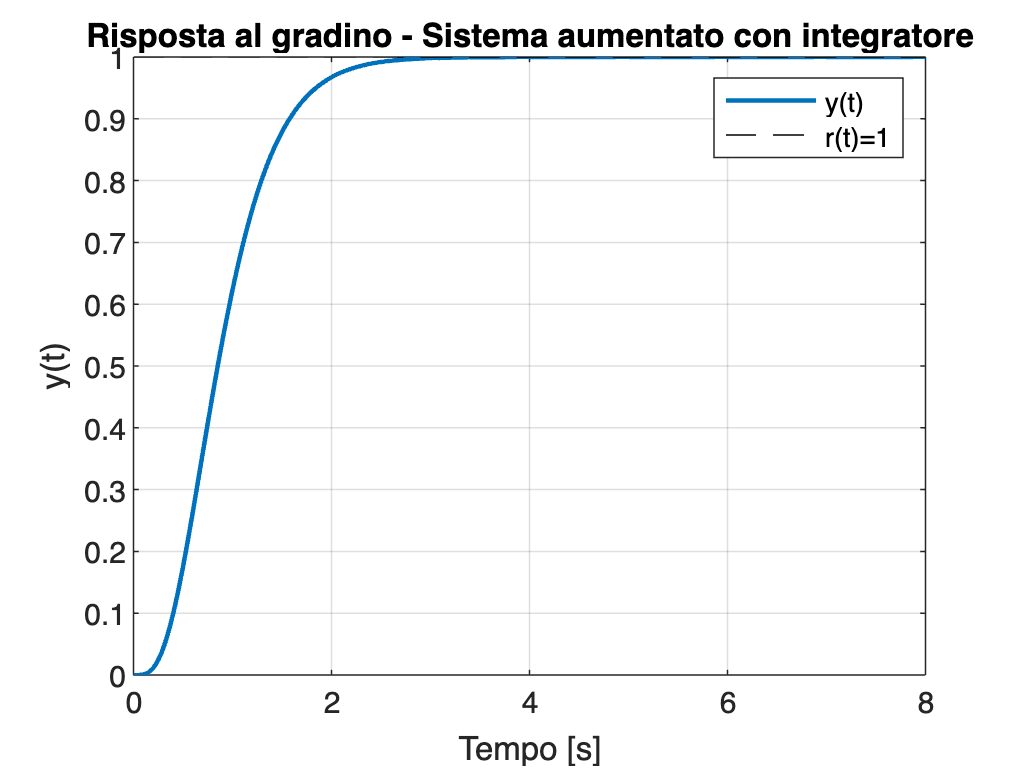


% metodo alternativo con inviluppo numerico semplice per la risoluzione
% dell'equazione differenziale
x0 = zeros(4,1);
r = 1;
dt = 0.01;
t = 0:dt:8;
x = x0;
yB = zeros(size(t));
for k=1:length(t)
    u = Kx*x(1:3) + Ki*x(4);
    dx = A_aug*x + B_aug*u + [0;0;0;1]*r;   % riferimento entra nell'equazione dell'integratore
    x = x + dt*dx;
    yB(k) = C_aug * x;
end

figure('Name','Parte B: risposta al gradino con integratore');
plot(t, yB, 'LineWidth', 1.5); hold on; plot(t, ones(size(t)), '--k');
grid on; title('Risposta al gradino - Sistema aumentato con integratore');
xlabel('Tempo [s]'); ylabel('y(t)'); legend('y(t)','r(t)=1');



%% Parte C: Passaggio al MIMO e uso di place + Sylvester
disp('--- Parte C: MIMO ---')

--- Parte C: MIMO ---


A = [0 1 0; 0 0 1; -6 -11 -6];
B2 = [0 0; 0 1; 1 0];   % 2 ingressi
disp('Rank controllability MIMO:'); disp(rank(ctrb(A,B2)));

Rank controllability MIMO:
     3



p_C = [-4 -5 -6];
%p_C = [-4 -4.01 -6];

% Metodo 1: place (KNV)
K_place = -place(A,B2,p_C);
fprintf('K_place = \n'); disp(K_place);

K_place = 
    6.0000   11.0000    2.0000
  -30.0000  -11.0000   -1.0000



fprintf('Poli anello chiuso (place): '); disp(eig(A + B2*K_place).');

Poli anello chiuso (place):    -5.0000   -6.0000   -4.0000




% Metodo 2: tentativi con Sylvester
% Formulazione: A*T - T*Lambda = -B*F  -> A*T + T*(-Lambda) = -B*F
Lambda = diag(p_C);
trials = 8;
found = false;
results = struct('trial',{}, 'resid',{}, 'condT',{}, 'K',{});
for i=1:trials
    F = rand(size(B2,2), size(A,1)); % m x n
    C_sylv = -B2*F;                    % n x n
    % utilizziamo sylvester per risolvere A*T + T*(-Lambda) = C_sylv
    T = sylvester(A, -Lambda, C_sylv);
    resid = norm(A*T - T*Lambda - C_sylv);
    condT = cond(T);
    if isfinite(condT)==0
        condT = Inf;
    end
    results(i).trial = i;
    results(i).resid = resid;
    results(i).condT = condT;
    if resid < 1e-8 && condT < 1e8 && rank(T)==size(T,1)
        K_sylv = F / T; % F * T^{-1}
        results(i).K = K_sylv;
        fprintf('Found candidate K via Sylvester at trial %d\n', i);
        fprintf('resid=%g, cond(T)=%g\n', resid, condT);
        fprintf('Poli A+BK_sylv: '); disp(eig(A + B2*K_sylv).');
        found = true;
        break;
    else
        results(i).K = [];
        fprintf('Trial %d: resid=%g, cond(T)=%g\n', i, resid, condT);
    end
end

Found candidate K via Sylvester at trial 1


resid=2.9899e-14, cond(T)=7792.82


Poli A+BK_sylv:    -6.0000   -5.0000   -4.0000




if ~found
    disp('Nessun F casuale ha prodotto T ben condizionata e compatibile nei tentativi effettuati.');
    disp('Usare place come approccio robusto, o cercare F con ottimizzazione mirata.');
end

%% Analisi numerica e consigli
disp('Risultati trial Sylvester:');

Risultati trial Sylvester:


for i=1:length(results)
    fprintf('trial %d: resid=%g, cond(T)=%g\n', results(i).trial, results(i).resid, results(i).condT);
end

trial 1: resid=2.9899e-14, cond(T)=7792.82



[Tplace,Dplace]=eig(A+B2*K_place);
[Tsylv,Dsylv]=eig(A+B2*K_sylv);
cond(Tplace)

ans = 62.0161

cond(Tsylv)

ans = 1.1442e+03

Tmod=zeros(size(T));
for i=1:length(T)
    Tmod(:,i)=T(:,i)/norm(T(:,i));
end
cond(Tmod)

ans = 1.1442e+03





fprintf('K_place = \n'); disp(K_place);

K_place = 
    6.0000   11.0000    2.0000
  -30.0000  -11.0000   -1.0000



fprintf('norm(K_place) = %g\n', norm(K_place));

norm(K_place) = 33.4356


fprintf('cond(Tplace) = %g\n', cond(Tplace));

cond(Tplace) = 62.0161


fprintf('K_sylv = \n'); disp(K_sylv);

K_sylv = 
  340.2579  111.9015    5.8593
  -37.2683  -14.8593   -1.3433



fprintf('norm(K_sylv) = %g\n', norm(K_sylv));

norm(K_sylv) = 360.467


fprintf('cond(Tsylv) = %g\n', cond(Tsylv));

cond(Tsylv) = 1144.18



fprintf('Suggerimento: se cond(T) è grande, la soluzione è mal condizionata e sensibile a perturbazioni.\n');

Suggerimento: se cond(T) è grande, la soluzione è mal condizionata e sensibile a perturbazioni.
